Function

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;
xx = linspace(0,0.8)

xx =          0    0.0081    0.0162    0.0242    0.0323    0.0404    0.0485    0.0566    0.0646    0.0727    0.0808    0.0889    0.0970    0.1051    0.1131    0.1212    0.1293    0.1374    0.1455    0.1535    0.1616    0.1697    0.1778    0.1859    0.1939    0.2020    0.2101    0.2182    0.2263    0.2343    0.2424    0.2505    0.2586    0.2667    0.2747    0.2828    0.2909    0.2990    0.3071    0.3152    0.3232    0.3313    0.3394    0.3475    0.3556    0.3636    0.3717    0.3798    0.3879    0.3960


yy = f(xx)

yy =     0.2000    0.3893    0.5546    0.6978    0.8209    0.9258    1.0140    1.0874    1.1474    1.1956    1.2334    1.2621    1.2829    1.2972    1.3059    1.3101    1.3108    1.3090    1.3054    1.3008    1.2960    1.2915    1.2881    1.2862    1.2863    1.2889    1.2943    1.3029    1.3148    1.3305    1.3500    1.3735    1.4010    1.4327    1.4686    1.5086    1.5527    1.6007    1.6527    1.7083    1.7675    1.8300    1.8956    1.9640    2.0349    2.1081    2.1832    2.2598    2.3377    2.4164


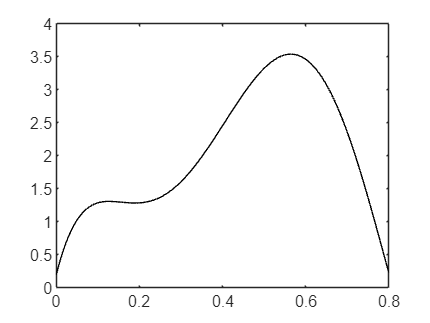

plot(xx,yy,'k-')

To integrate function from 0 to 0.8

a = 0

a = 0

b = 0.8

b = 0.8000

p = [400 -900 675 -200 25 0.2]

p =   400.0000 -900.0000  675.0000 -200.0000   25.0000    0.2000


q = polyint(p)

q =    66.6667 -180.0000  168.7500  -66.6667   12.5000    0.2000         0


Itrue = diff(polyval(q,[a,b]))

Itrue = 1.6405

Plot original function along with simpson 1/3 rule with ns = 1

ns = 1

ns = 1

x = linspace(a,b,2*ns+1)

x =          0    0.4000    0.8000


y = f(x)

y =     0.2000    2.4560    0.2320



p2 = polyfit(x,y,2)

p2 =   -14.0000   11.2400    0.2000


yy2 = polyval(p2,xx)

yy2 =     0.2000    0.2899    0.3780    0.4643    0.5487    0.6313    0.7121    0.7910    0.8681    0.9434    1.0169    1.0885    1.1583    1.2263    1.2924    1.3567    1.4192    1.4799    1.5387    1.5957    1.6509    1.7042    1.7558    1.8054    1.8533    1.8993    1.9435    1.9859    2.0265    2.0652    2.1021    2.1371    2.1704    2.2018    2.2314    2.2591    2.2850    2.3091    2.3314    2.3518    2.3704    2.3872    2.4022    2.4153    2.4266    2.4360    2.4437    2.4495    2.4535    2.4556


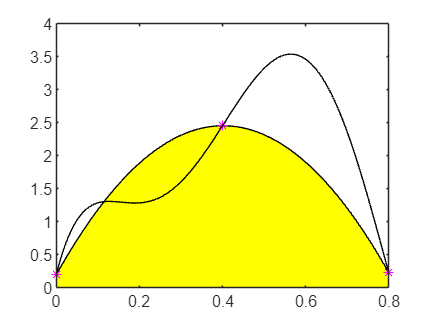

figure
area(xx,yy2,'FaceColor','y','EdgeColor','black','LineStyle','-')
hold on
plot(x,y,'m*')
plot(xx,yy,'k-')

Plot original function along with simpson 1/3 rule with ns = 2

ns = 2

ns = 2

x = linspace(a,b,2*ns+1)

x =          0    0.2000    0.4000    0.6000    0.8000


y = f(x)

y =     0.2000    1.2880    2.4560    3.4640    0.2320



figure
color = ['g','y']

color = 'gy'

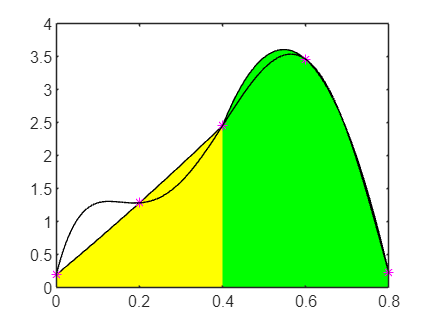

for i = 1:ns
    il = 2*(i-1)+1;
    ir = 2*i+1;
    newx = x(il:ir);
    newy = y(il:ir);
    p2 = polyfit(newx,newy,2);
    xx2 = linspace(x(il),x(ir));
    yy2 = polyval(p2,xx2);
    area(xx2,yy2,'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
    hold on
    plot(x(il:ir),y(il:ir),'m*')
    hold on
end
plot(xx,yy,'k-')

Plot original function along with simpson 1/3 rule with ns = 3

ns = 3

ns = 3

x = linspace(a,b,2*ns+1)

x =          0    0.1333    0.2667    0.4000    0.5333    0.6667    0.8000


y = f(x)

y =     0.2000    1.3102    1.4327    2.4560    3.4872    2.8749    0.2320



figure
color = ['g','y']

color = 'gy'

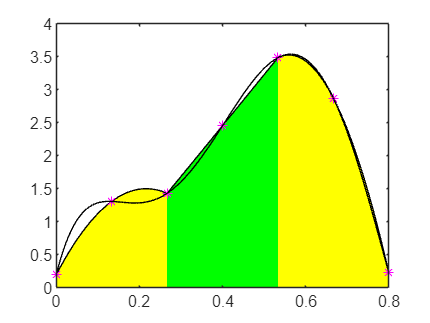

for i = 1:ns
    il = 2*(i-1)+1;
    ir = 2*i+1;
    newx = x(il:ir);
    newy = y(il:ir);
    p2 = polyfit(newx,newy,2);
    xx2 = linspace(x(il),x(ir));
    yy2 = polyval(p2,xx2);
    area(xx2,yy2,'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
    hold on
    plot(x(il:ir),y(il:ir),'m*')
    hold on
end
plot(xx,yy,'k-')

Plot original function along with simpson 1/3 rule from ns = 1 to 10